
clear all; close all; clc; rng(1);

% set data path
currentDir = pwd;
exptDir = currentDir(1:regexp(pwd,'03expCode')-1);
outDir = [exptDir '02figures/fig4_best_model_prediction'];
addpath(genpath([exptDir '03ExpCode/05functions']));
addpath(genpath([exptDir '03ExpCode/01pretest/data']));
addpath(genpath([exptDir '03ExpCode/04posttest/data']));
addpath('./model_comparison_function_v5')

load('a04_mc_results_v5_n10.mat')
load('RandomAdaptorOrder.mat' );

% define subjects and sessions to use
% all the following operations are based on sub2use
sub = 1:10;
n_sub = numel(sub);
sub_slc = [1:4,6:10]; % exclude sub5
n_sub2use = numel(sub_slc);
adaptor_soa = [-700, -300, -200, -100,  0,  100, 200, 300, 700];
n_adaptor_soa = numel(adaptor_soa);
all_adaptor = 1:n_adaptor_soa;

%% extract key parameters from the best fitting model
% extract the best model across 9 sessions based on delta_AIC
[row col] = find(deltaAIC == 0);
perBestModel = NaN(1,n_sub);
perBestModel(row) = col;

% pre-allocate
[delta_mu,sigma_pre,sigma_post, sigma_ave] = deal(NaN(n_sub, n_adaptor_soa));

% all the extracted parameters are ordered by adaptor_soa instead of
% sessions
for sub = sub_slc

    bestModel = perBestModel(sub);

    % sort by adaptor soa
    i_adaptor_soa = randomAdaptorOrder(sub,:);
    [sorted_adaptor_soa, order] = sort(i_adaptor_soa);

    counter = 1;
    for sess = order
        switch bestModel
            case 1 % M1
                % delta_mu = post_mu - pre_mu
                delta_mu(sub,counter) = estP{sub}{sess,bestModel}(2) - estP{sub}{sess,bestModel}(1);
                % average sigma between pre and post test
                sigma_pre(sub,counter) = estP{sub}{sess,bestModel}(3);
                sigma_post(sub,counter) = estP{sub}{sess,bestModel}(4);
                sigma_ave(sub,counter) = (sigma_pre(sub,counter) + sigma_post(sub,counter))/2;
         
            case 2 % M2
                % delta_mu = post_mu - pre_mu
                delta_mu(sub,counter) = estP{sub}{sess,bestModel}(2) - estP{sub}{sess,bestModel}(1);
                % take only one sigma as the average sigma
                sigma_ave(sub,counter) = estP{sub}{sess,bestModel}(3); % only 1 sigma
        end

        counter = counter + 1;
    end

end


## scatter plot: x= sigma, y = |delta_PSS|, color code = adaptor SOA

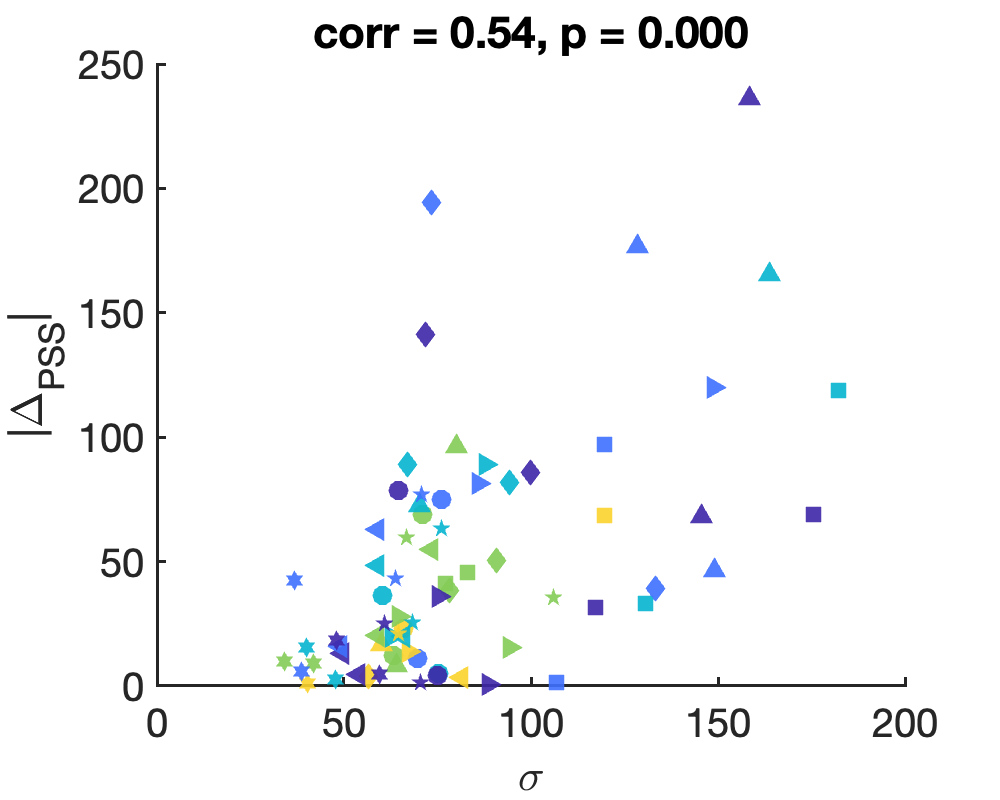

% using best-fitting parameters, plot sigma against delta_PSS, color coded by session, code by subjects

% color code: adaptor SOA (9 levels)
n_color = numel(adaptor_soa);
cmap = parula;
cidx = floor(linspace(1,230, ceil(n_color/2)));
cidx = [cidx, fliplr(cidx(1:end-1))]; % yellow: small adaptor SOA magnitude; blue: larger adaptor SOA magnitude

% marker: subject
markers = ['o','s','d','^','v','>','<','p','*','h'];

figure; hold on
set(gcf,'position',[0 0 500 400]);
set(gca, 'LineWidth', 1.5, 'FontSize', 20); 

for sub = sub_slc
    for t = 1:numel(adaptor_soa)
    scatter(sigma_ave(sub, t), abs(delta_mu(sub, t)), 100, markers(sub), ...
        'MarkerFaceColor',cmap(cidx(t),:), 'MarkerEdgeColor','none', ...
        'MarkerFaceAlpha', 0.9);
    end
end

% correlation test
sigma_ave_slc = sigma_ave(sub_slc,:);
delta_mu_slc = delta_mu(sub_slc,:);

[rho pval] = corr(abs(delta_mu_slc(:)), sigma_ave_slc(:));

% look better
xlabel('\sigma'); ylabel('|\Delta_{PSS}|');
ttl = sprintf('corr = %.2f, p = %.3f', rho, pval);
title(ttl)

% save figure
flnm = 'fig4_corr_sigma_dPSS1';
saveas(gca, fullfile(outDir, flnm), 'epsc')

## scatter plot: x= sigma, y = |delta_PSS|, color code = subjects

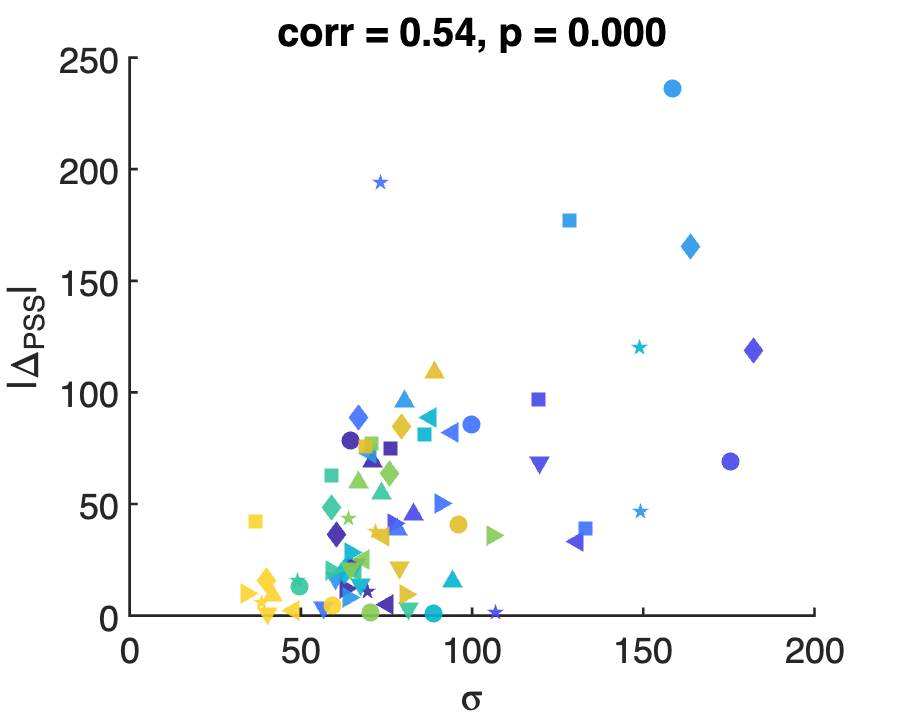

%% scatter plot
% using best-fitting parameters, plot sigma against delta_PSS, color coded by session, code by subjects

% color code: subjects
n_color = numel(sub_slc);
cmap = parula;
cidx = floor(linspace(1,230, n_color));

% marker: subject
markers = {'o','s','d','^','v','>','<','p','*','h'};

figure; hold on
set(gcf,'position',[0 0 500 400]);
set(gca, 'LineWidth', 1.5, 'FontSize', 20); 


for sub = sub_slc
    for t = 1:numel(adaptor_soa)
        idx_sub = find(sub_slc==sub);
        scatter(sigma_ave(sub, t), abs(delta_mu(sub, t)), 100, markers{t}, ...
        'MarkerFaceColor',cmap(cidx(idx_sub),:), 'MarkerEdgeColor','none', ...
        'MarkerFaceAlpha', 0.9);
    end

end

% correlation test
sigma_ave_slc = sigma_ave(sub_slc,:);
delta_mu_slc = delta_mu(sub_slc,:);

[rho pval] = corr(abs(delta_mu_slc(:)), sigma_ave_slc(:));

% look better
xlabel('\sigma'); ylabel('|\Delta_{PSS}|');
ttl = sprintf('corr = %.2f, p = %.3f', rho, pval);
title(ttl)


% save figure
% flnm = 'fig4_corr_sigma_dPSS';
% saveas(gca, fullfile(outDir, flnm), 'epsc')

## scatter plot: x= sigma, y = |delta_PSS|, averaged aross sessions

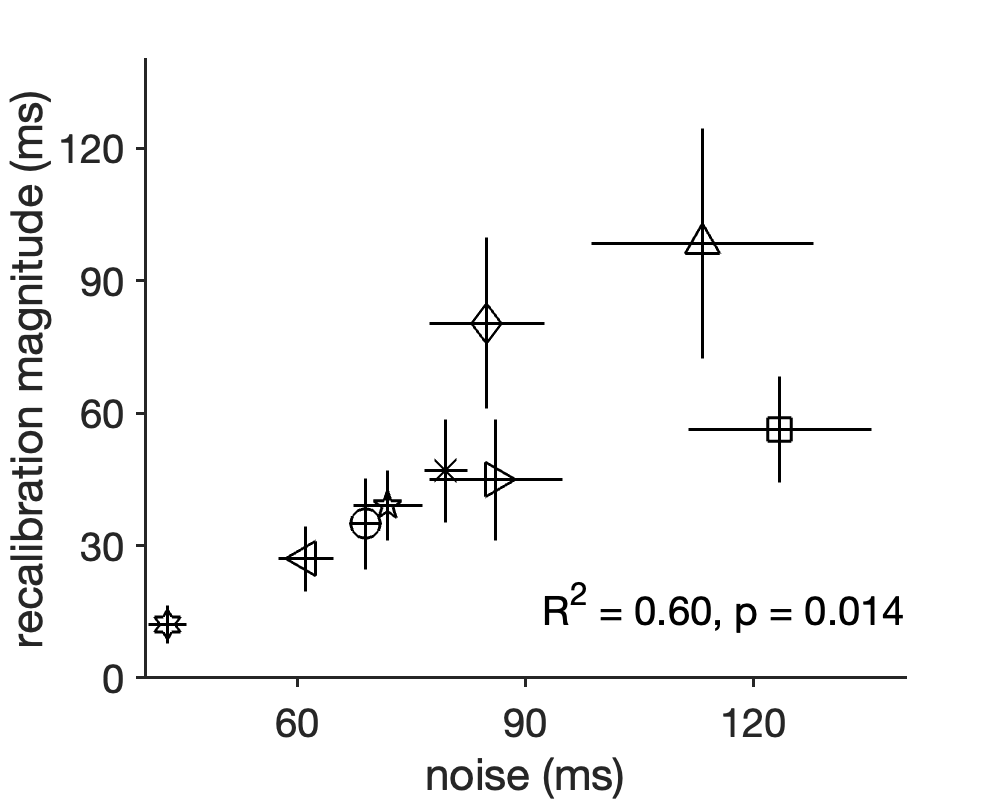

% calculate mean and se across sessions, for each individual
mean_mu = mean(abs(delta_mu(sub_slc,:)), 2);
se_mu = std(abs(delta_mu(sub_slc,:)), [], 2)./sqrt(numel(all_adaptor));
mean_sigma = mean(sigma_ave(sub_slc,:), 2);
se_sigma = std(sigma_ave(sub_slc,:), [], 2)./sqrt(numel(all_adaptor));

% plotting
figure;hold on; box off;
set(gca, 'FontSize', 20, 'LineWidth', 1.5)
set(gcf, 'Position',[10 10 500 400])
markers = ['o','s','d','^','v','>','<','p','*','h'];

for s = 1:numel(sub_slc)
    idx_sub = sub_slc(s);
    e = errorbar(mean_sigma(s), mean_mu(s), ...
        se_mu(s), se_mu(s), se_sigma(s), se_sigma(s), ...
    markers(idx_sub), 'LineWidth',1.5,'MarkerSize',15, 'Color','k');
    e.CapSize = 0;  
end

% % add least-square line
% scatter(mean_sigma, mean_mu, 1, zeros(1,3));
% l1 = lsline;
% l1.LineWidth = 2;

% add correlation 
[rho pval] = corr(mean_sigma, mean_mu);
corr_text = sprintf('R^2 = %.2f, p = %.3f', rho^2, pval);
text(140, 10, corr_text, ...
     'HorizontalAlignment', 'right', ...
     'VerticalAlignment', 'bottom', ...
     'FontSize',20,...
     'FontName','Helvetica');

% look better
xlabel('noise (ms)'); ylabel('recalibration magnitude (ms)');
yl = ylim; yticks([0:30:150]);
xl = xlim; xticks([30:30:150])
set(gca,'TickDir','out');

% save figure
flnm = 'fig4_corr_sigma_dPSS2';
saveas(gca, fullfile(outDir, flnm), 'epsc')

## scatter plot: x= sigma, y = |delta_PSS|, subplots for small/large adaptor SOA magnitude

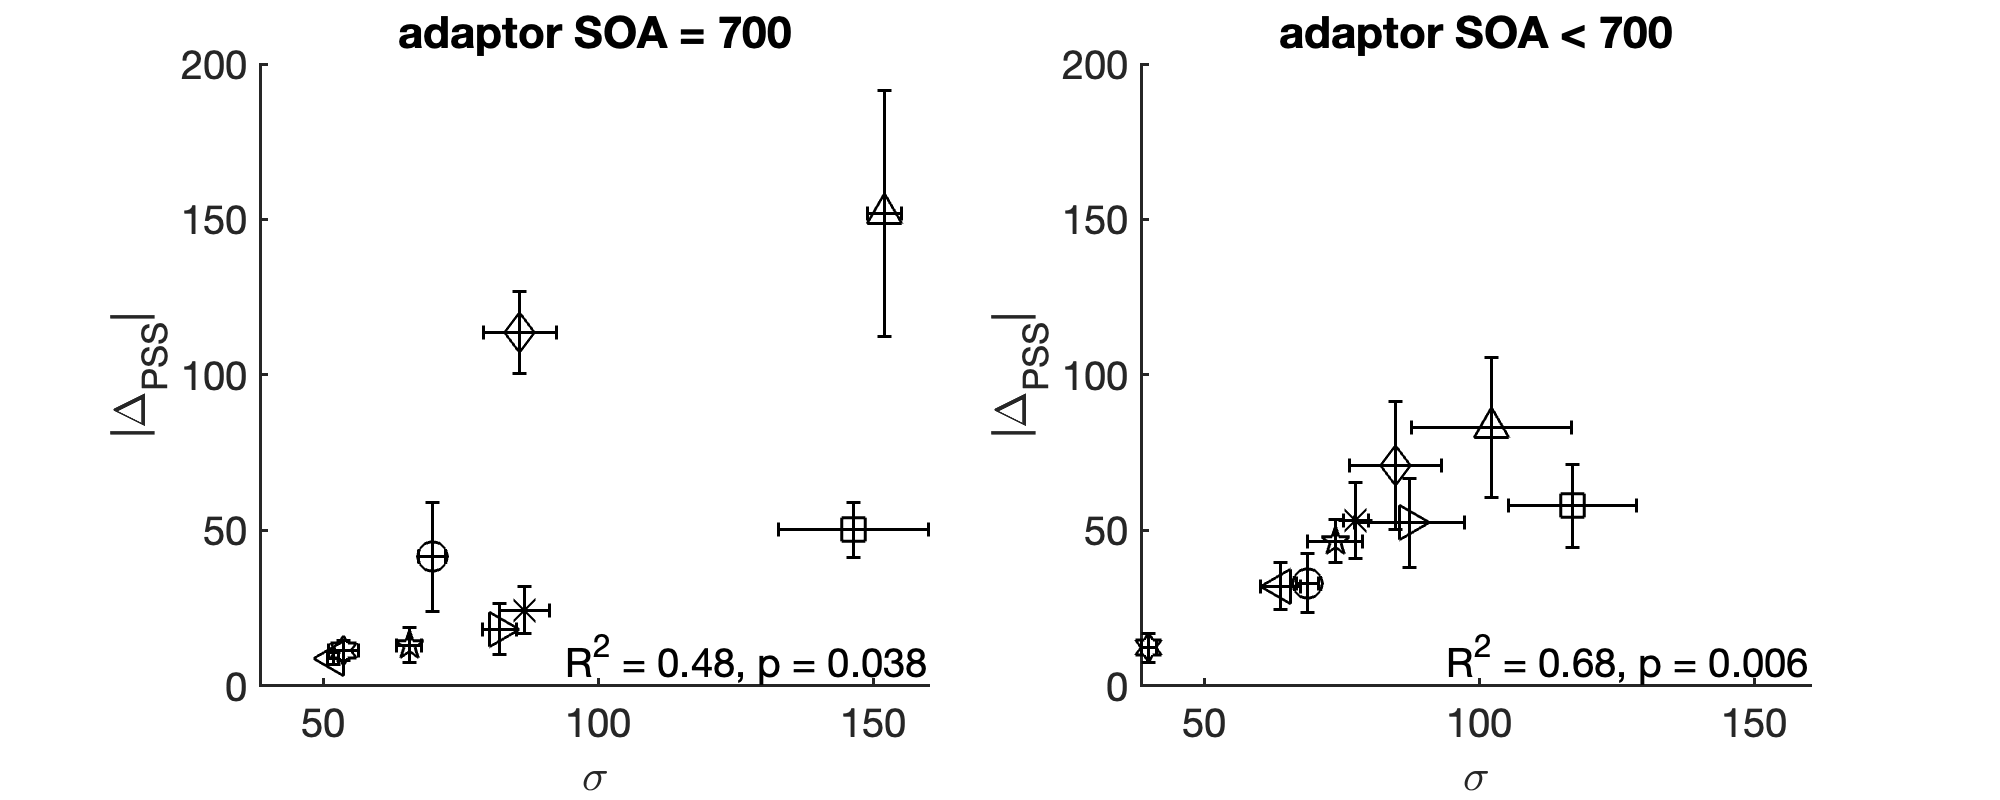

group_adaptor_soa = {[1,9], [2, 3,4,5,6,7,8]}; % row1: large adaptor SOA magnitude; row2: small adaptor SOA magnitude
titles = {'adaptor SOA = 700', 'adaptor SOA < 700'};
figure;
set(gcf, 'Position',[10 10 1000 400])

for g = 1:2

    adaptor_soa_slc = group_adaptor_soa{g};
    % calculate mean and se across sessions, for each individual
    mean_mu = mean(abs(delta_mu(sub_slc,adaptor_soa_slc)), 2);
    se_mu = std(abs(delta_mu(sub_slc,adaptor_soa_slc)), [], 2)./sqrt(numel(all_adaptor));
    mean_sigma = mean(sigma_ave(sub_slc,adaptor_soa_slc), 2);
    se_sigma = std(sigma_ave(sub_slc,adaptor_soa_slc), [], 2)./sqrt(numel(all_adaptor));

    % plotting
    pl(g) = subplot(1,2,g);
    hold on; box off;
    set(gca, 'FontSize', 20, 'LineWidth', 1.5)
%     set(gcf, 'Position',[10 10 500 400])
    markers = ['o','s','d','^','v','>','<','p','*','h'];

    for s = 1:numel(sub_slc)
        idx_sub = sub_slc(s);
        errorbar(mean_sigma(s), mean_mu(s), ...
            se_mu(s), se_mu(s), se_sigma(s), se_sigma(s), ...
            markers(idx_sub), 'LineWidth',1.5,'MarkerSize',15, 'Color','k')
    end

%     % add least-square line
%     scatter(mean_sigma, mean_mu, 1, zeros(1,3));
%     l1 = lsline;
%     l1.LineWidth = 2;

    % add correlation
    [rho pval] = corr(mean_sigma, mean_mu);
    corr_text = sprintf('R^2 = %.2f, p = %.3f', rho^2, pval);
    text(160, 0, corr_text, ...
        'HorizontalAlignment', 'right', ...
        'VerticalAlignment', 'bottom', ...
        'FontSize',20,...
        'FontName','Helvetica');

    % look better
    xlabel('\sigma'); ylabel('|\Delta_{PSS}|');
    title(titles{g})

end

linkaxes([pl], 'xy')
save figure
flnm = 'fig4_corr_sigma_dPSS3';
saveas(gca, fullfile(outDir, flnm), 'epsc')

### scatter plot: x= sigma, y = |delta_PSS|, subplots for small/large adaptor SOA magnitude